%% Import

close all;
clc;
clear;
path = '/Users/Lorenzo/Desktop/Tesi/BankClients.mat';

load(path)

Data = BankClients; % renaming (we don't touch the original matrix)



%DATI SINTETICI

%questi importati da Gretel.ai; quando importo devo controllare max e min
%delle colonne e sostituire le virgole coi punti o non importa
%correttamente in Matlab

Synt=readtable('/Users/Lorenzo/Desktop/Tesi/Sintetici100k.csv');

%devo rendere le variabili omogenee

Synt.Age=double(Synt.Age);
Data.Age=double(Data.Age);

Synt.Gender=categorical(Synt.Gender);
Data.Gender=categorical(Data.Gender);

Synt.Job=categorical(Synt.Job);
Data.Job=categorical(Data.Job);

Synt.Area=categorical(Synt.Area);
Data.Area=categorical(Data.Area);

Synt.CitySize=categorical(Synt.CitySize);
Data.CitySize=categorical(Data.CitySize);

Synt.Investments=categorical(Synt.Investments);
Data.Investments=categorical(Data.Investments);

%metto insieme i dati

DataAll=[Synt(:,1:17); Data(:,2:18)];

%rendo le categoriche da 0

DataAll.Job=int8(DataAll.Job);
DataAll.Job=DataAll.Job-1;

DataAll.Area=int8(DataAll.Area);
DataAll.Area=DataAll.Area-1;

DataAll.CitySize=int8(DataAll.CitySize);
DataAll.CitySize=DataAll.CitySize-1;

DataAll.Investments=int8(DataAll.Investments);
DataAll.Investments=DataAll.Investments-1;

%faccio anche con Data ce poi rappresenterò

Data=[Data(:,2:18)];

Data.Investments=int8(Data.Investments);
Data.Investments=Data.Investments-1;


%check of uniqueness

[uniqueRows, ia, ic] = unique(DataAll, 'rows'); % son tutte diverse

%teniamo lo stesso numero di righe per ogni classe

rows_cat0 = DataAll(DataAll.Investments == 0, :);
rows_cat1 = DataAll(DataAll.Investments == 1, :);
rows_cat2 = DataAll(DataAll.Investments == 2, :);

min_count = min([height(rows_cat0), height(rows_cat1), height(rows_cat2)]);

balanced_cat0 = rows_cat0(1:min_count, :);
balanced_cat1 = rows_cat1(1:min_count, :);
balanced_cat2 = rows_cat2(1:min_count, :);
DataAllBal = [balanced_cat0; balanced_cat1; balanced_cat2];


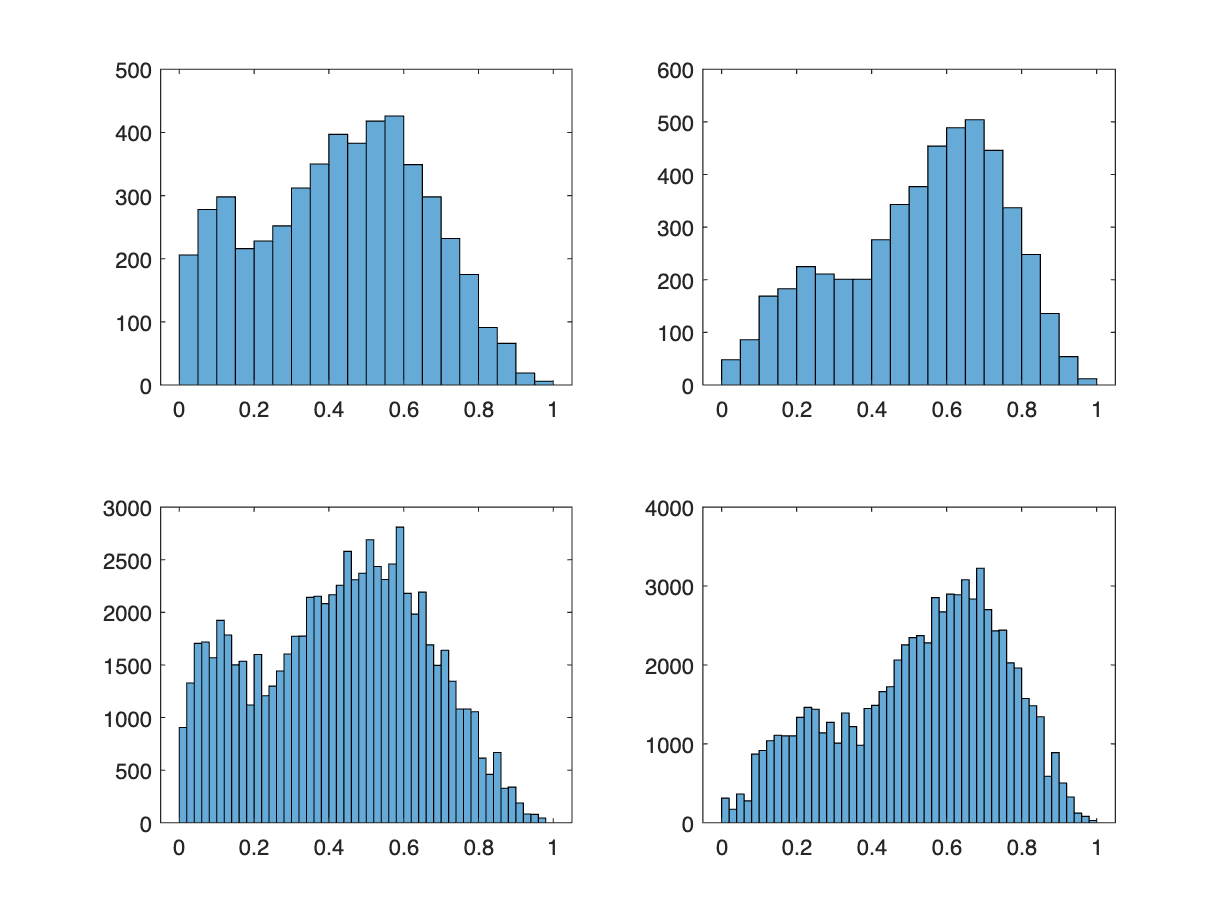

% useful transformations

figure
subplot(2,2,1)
histogram(Data.Debt);
subplot(2,2,2)
histogram(Data.Debt.^0.7); % seems best
subplot(2,2,3)
histogram(DataAllBal.Debt);
subplot(2,2,4)
histogram(DataAllBal.Debt.^0.7);

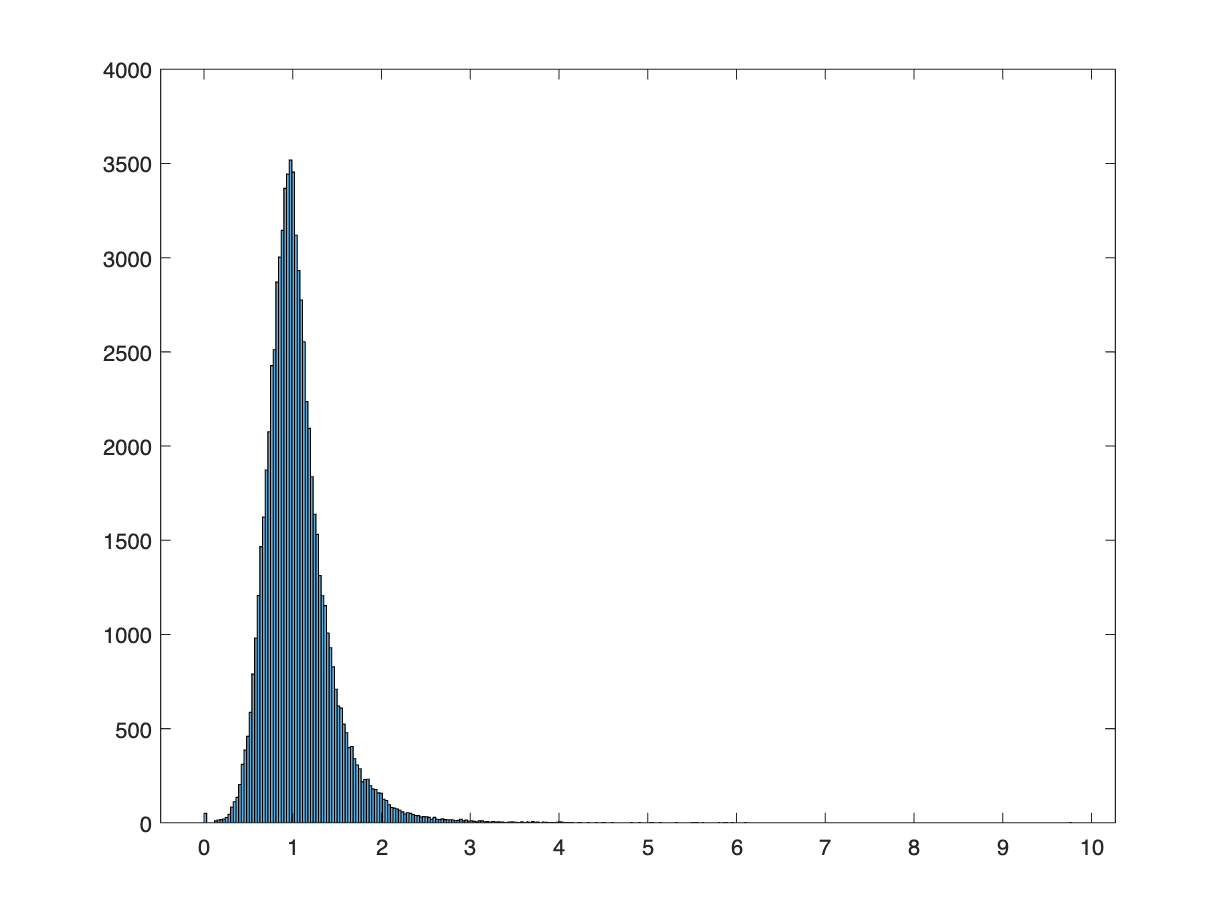

nobs=size(DataAllBal,1);

IncWealthRatio=zeros(nobs,1);

IncWealthRatio(DataAllBal.Wealth>0) = DataAllBal.Income(DataAllBal.Wealth>0)./DataAllBal.Wealth(DataAllBal.Wealth>0);

figure
histogram(IncWealthRatio.^0.5); % secondo me posso tenerlo così

% creo tabella da elaborare con dati sintetici

xnumnames = {'age','familysize','income','wealth', 'debt', 'finedu','esg','digital','bankfriend','lifestyle','luxury','savings'};

xnames = DataAllBal.Properties.VariableNames(1:16); %tolgo ID
gen=double(DataAllBal.Gender);

X =[rescale(DataAllBal.Age) double(DataAllBal.Gender) double(DataAllBal.Job)...
    double(DataAllBal.Area) double(DataAllBal.CitySize) rescale(DataAllBal.FamilySize)...
    DataAllBal.Income DataAllBal.Wealth DataAllBal.Debt.^0.7 DataAllBal.FinEdu...
    DataAllBal.ESG DataAllBal.Digital DataAllBal.BankFriend DataAllBal.LifeStyle...
    DataAllBal.Luxury DataAllBal.Saving];

Xtab=table(X(:,1), X(:,2), X(:,3), X(:,4), X(:,5), X(:,6), X(:,7), X(:,8),...
    X(:,9), X(:,10), X(:,11), X(:,12), X(:,13), X(:,14), X(:,15), X(:,16)...
    , 'VariableNames',xnames);

Xtab.Gender = categorical(Xtab.Gender);
Xtab.Job = categorical(Xtab.Job);
Xtab.Area = categorical(Xtab.Area);
Xtab.CitySize = categorical(Xtab.CitySize);


% con la funzione class(Data.colonna) vedo il tipo

% aggiungo radice di income/wealth

Xtab.("IncWealthRatio")=IncWealthRatio.^0.5;

Xtab.IncWealthRatio=rescale(Xtab.IncWealthRatio);



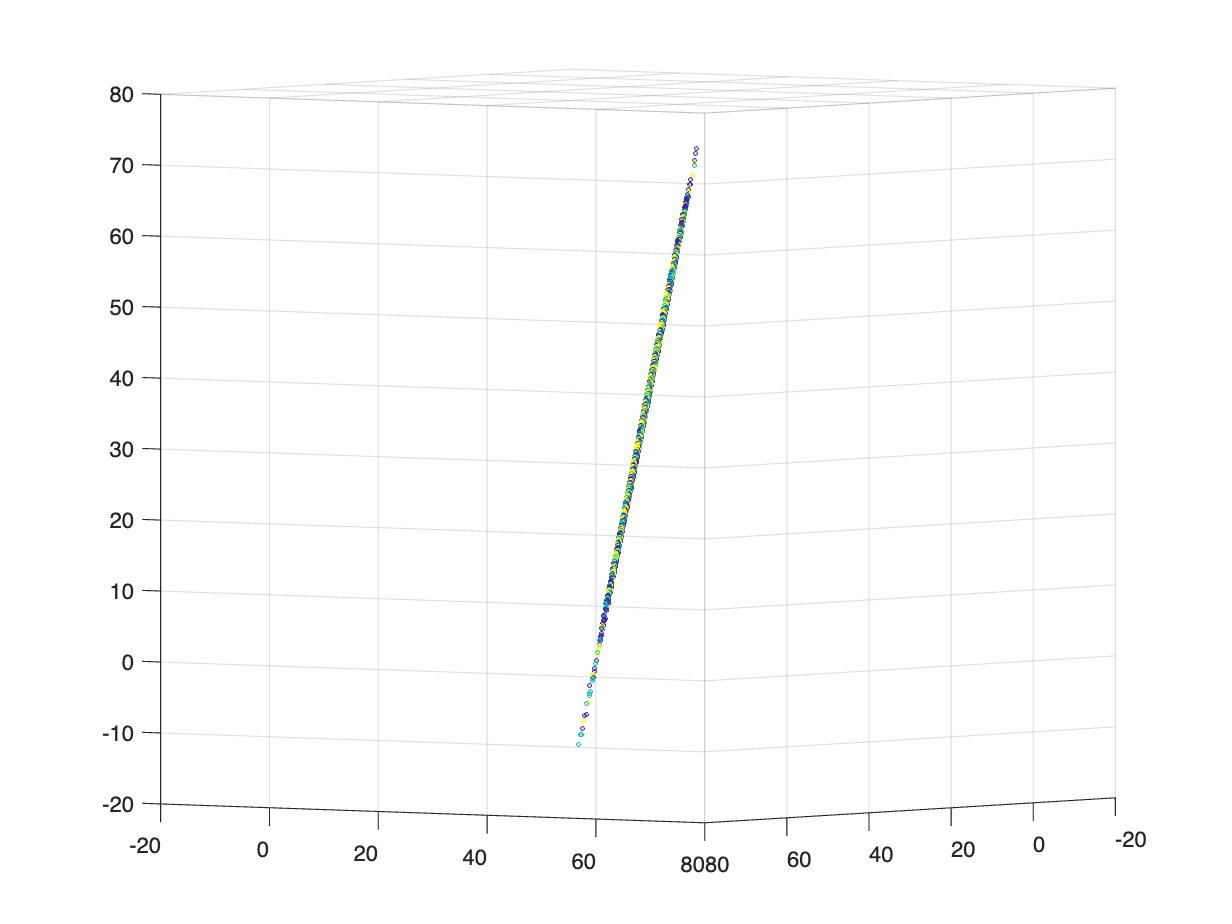

XNum=[X(:,1), X(:,6), X(:,7), X(:,8), X(:,9), X(:,10),...
    X(:,11), X(:,12), X(:,13), X(:,14), X(:,15), X(:,16)];

Y=categorical(DataAllBal.Investments);

W=LDA(XNum,Y);

L = [ones(nobs,1) XNum] * W';

%visualizziamo il risultato

figure()
scatter3(L(:,1),L(:,2),L(:,3),repmat(3,nobs,1),Y);

%faccio lo stesso coi dati originali senza sintetici per poi plottare

XSmall =[rescale(Data.Age) rescale(Data.FamilySize)...
    Data.Income Data.Wealth Data.Debt.^0.7 Data.FinEdu...
    Data.ESG Data.Digital Data.BankFriend Data.LifeStyle...
    Data.Luxury Data.Saving];


YSmall=categorical(Data.Investments);



%LDA

W=LDA(XSmall, YSmall)

W =   -21.0573   11.5419    5.6013    2.7416    2.7208    5.9626    1.3511   15.6785    3.5609   16.0373    2.6149   -2.1974    8.5303
  -22.4140   11.9561    5.0870    2.9487    3.2547    5.3756    2.3445   16.3211    3.0318   17.0372    2.2183   -1.5378    8.4017
  -22.4077   11.5622    5.5653    3.1580    3.1100    6.9431    2.1814   16.0032    3.2793   15.6564    2.5267   -1.8525    9.5320



XSmallLda = [ones(5000,1) XSmall] * W';


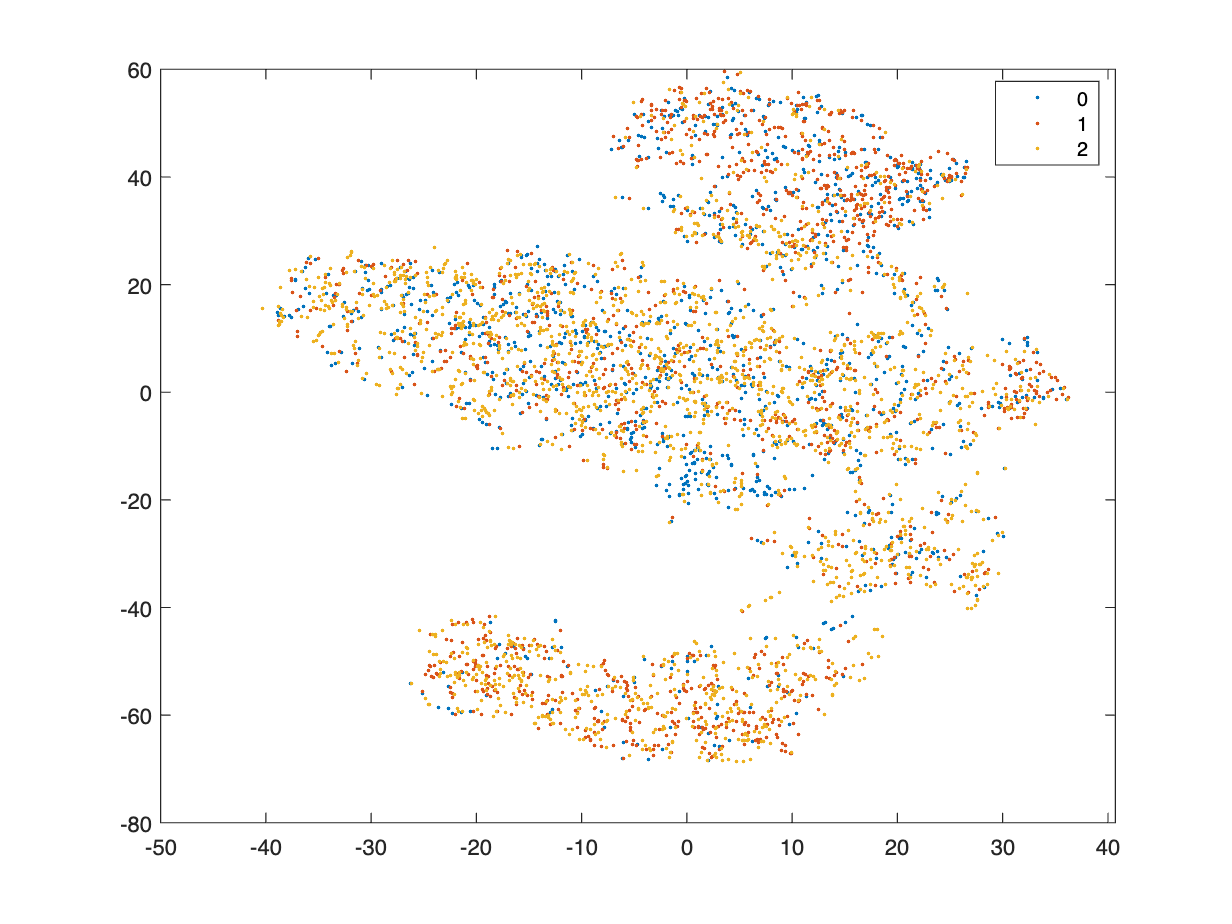

%per plottare uso TSNE

Tsne2=tsne(XSmall);

gscatter(Tsne(:,1),Tsne(:,2),YSmall);

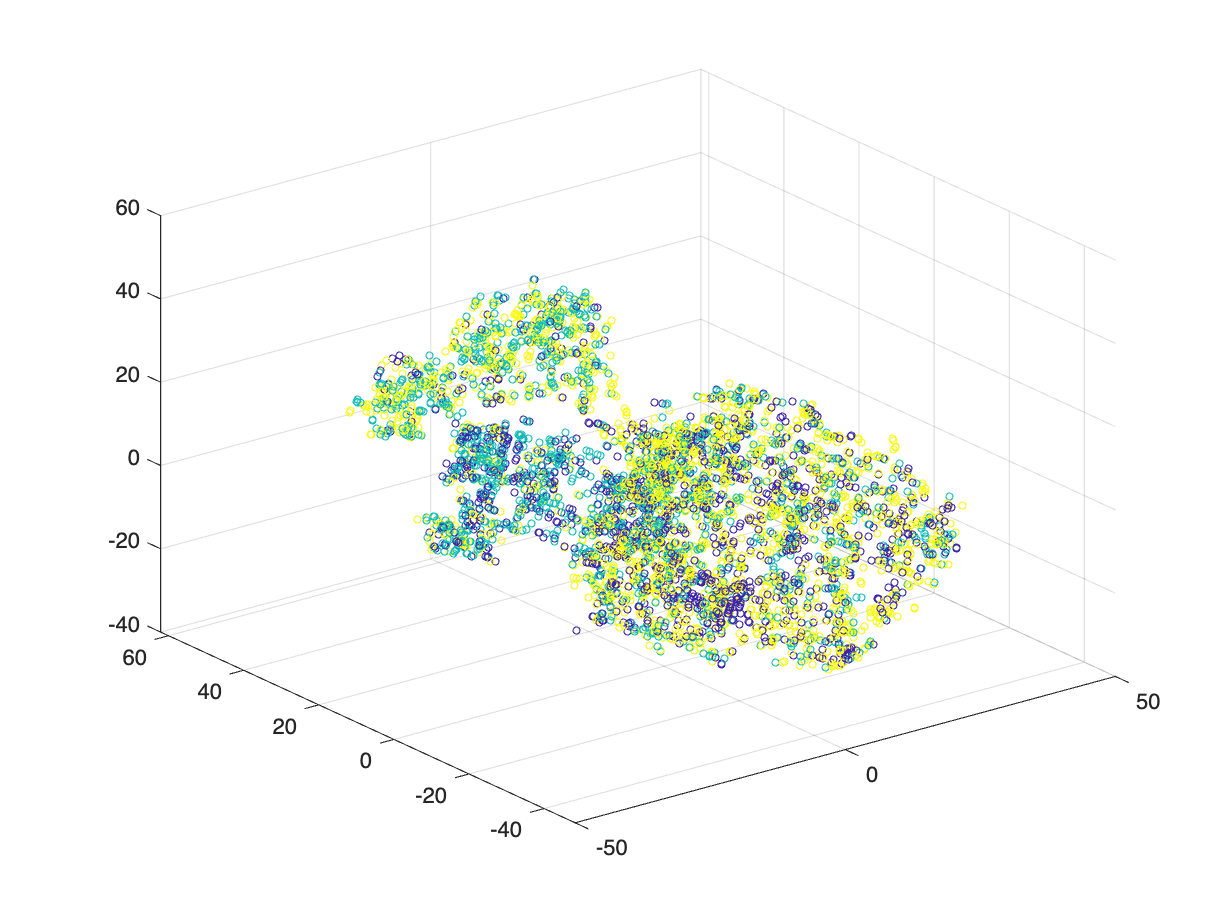


Tsne3=tsne(XSmall, "NumDimensions",3);

scatter3(Tsne3(:,1),Tsne3(:,2),Tsne3(:,3),repmat(10,numel(YSmall),1),YSmall);

% creo risposte

Y = categorical(DataAllBal.Investments);

YLump = zeros(nobs,1);

YLump (Y=="1")=1;

YCap = zeros(nobs,1);

YCap (Y=="2")=1;




%% Riduzione dataset

Xtab.Gender=[];
Xtab.Area=[];
Xtab.FamilySize=[];

## MODELLO CON CLASS. TREE

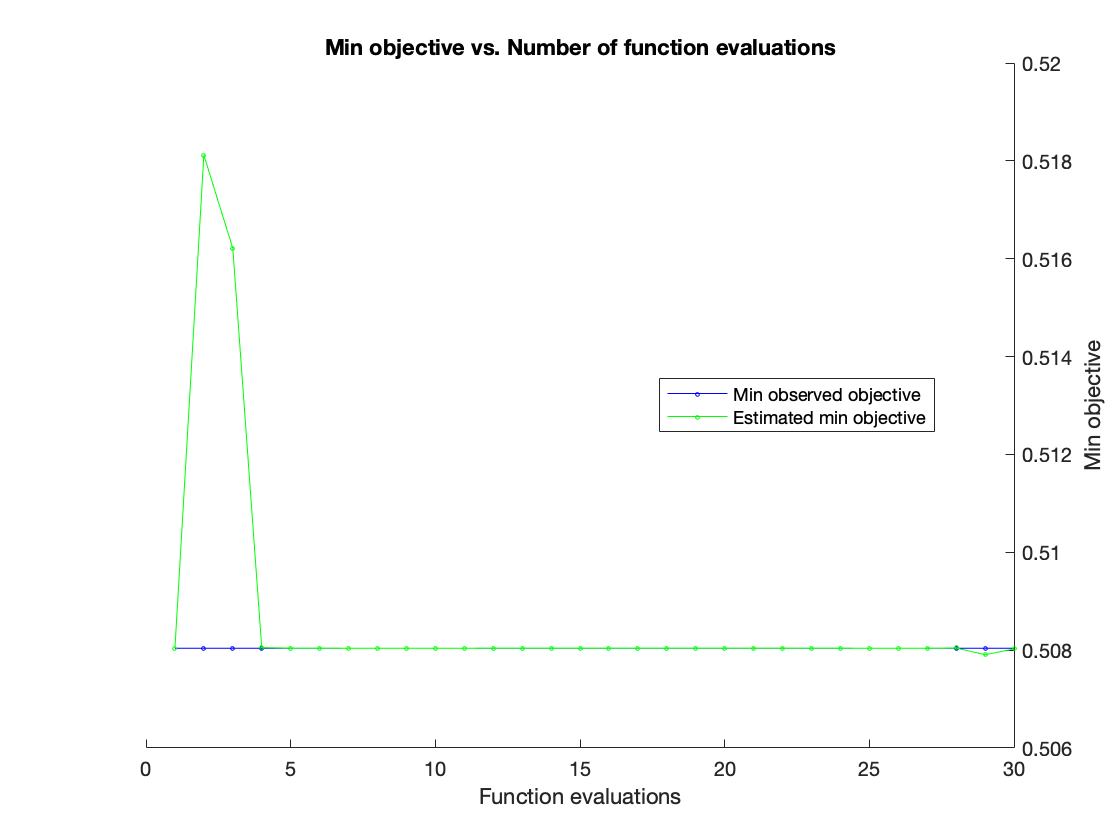


% Creare un template per l'albero di classificazione
t = templateTree('MaxNumSplits', 7);

% Ottimizzare i parametri utilizzando la cross-validation
% Eseguire una ricerca di iperparametri con ottimizzazione bayesiana
cvp = cvpartition(Y, 'KFold', 10); % 10-fold cross-validation
opts = struct('Optimizer', 'bayesopt', 'CVPartition', cvp, ...
              'AcquisitionFunctionName', 'expected-improvement-plus', ...
              'ShowPlots', true, 'Verbose', 0);

% Definire il modello di classificazione
Mdl = fitcensemble(Xtab, Y, 'Method', 'Bag', 'Learners', t, ...
                   'OptimizeHyperparameters', 'auto', 'HyperparameterOptimizationOptions', opts);


% Visualizzare il migliore modello trovato
disp(Mdl)

  ClassificationBaggedEnsemble
                       PredictorNames: {1×14 cell}
                         ResponseName: 'Y'
                CategoricalPredictors: [2 3]
                           ClassNames: [0    1    2]
                       ScoreTransform: 'none'
                      NumObservations: 105000
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 35
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     UseObsForLearner: [105000×35 logical]


  


% Valutare la performance del modello con cross-validation
CVModel = crossval(Mdl, 'KFold', 5);
loss = kfoldLoss(CVModel);
disp(['Cross-validated classification loss: ', num2str(loss)])

Cross-validated classification loss: 0.50804



% Fare previsioni con il modello addestrato
predictions = predict(Mdl, Xtab);

% Visualizzare la matrice di confusione
confMat = confusionmat(Y, predictions);
disp('Confusion Matrix:')

Confusion Matrix:


disp(confMat)

           0       25037           0
           0       51656           0
           0       28307           0

